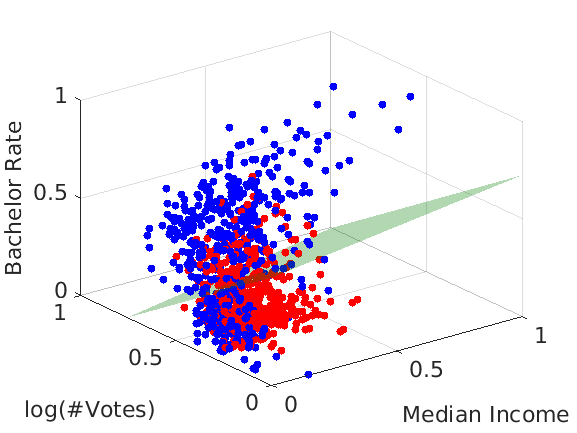

% retrieving data
[~,~, y, X] = Project1main_q2();

[n,dim] = size(X);
Y = (y*ones(1,dim+1)).*[X ones(n,1)];
lambda = 0.01;
fun = @(I,Y,w)fun0(I,Y,w,lambda);
gfun = @(I,Y,w)gfun0(I,Y,w,lambda);
nsteps = 1000;
nruns = 1000;
x0 = [0.5;0.5;0.5;0.5];

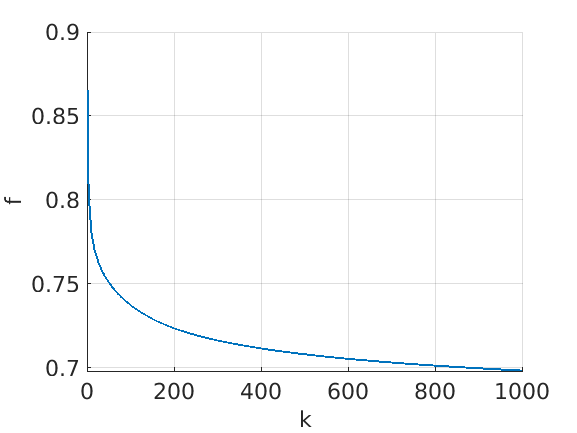

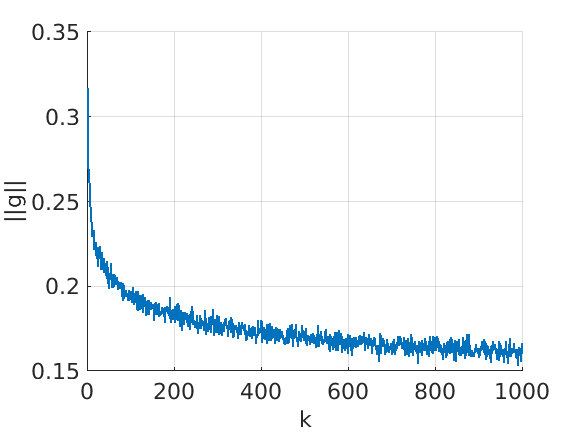

%% batch size:
alpha_strat = 'slow'; M = 10;
%%% 1. ng=20, nh=50;
ng = 20; nh = 50;
[fs, gs, runtime1] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_20_50')

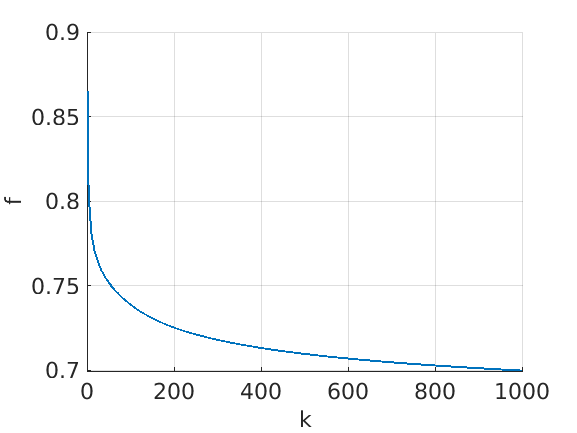

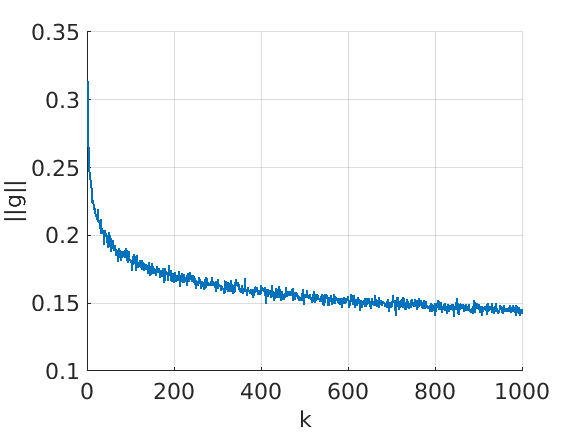

%%% 2. ng=40, nh=100;
ng = 40; nh = 100;
[fs, gs, runtime2] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_40_100')

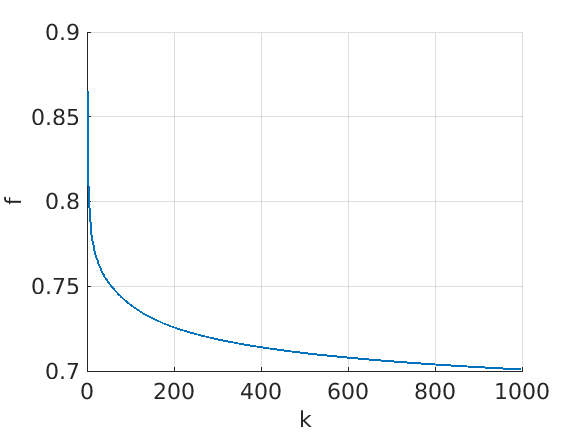

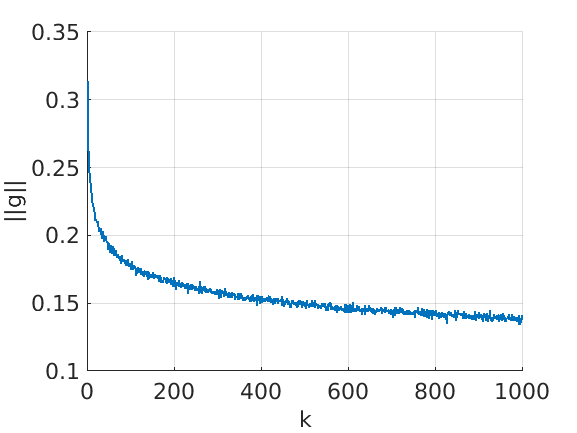

%%% 3. ng=100, nh=200;
ng = 100; nh = 200;
[fs, gs, runtime3] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_100_200')

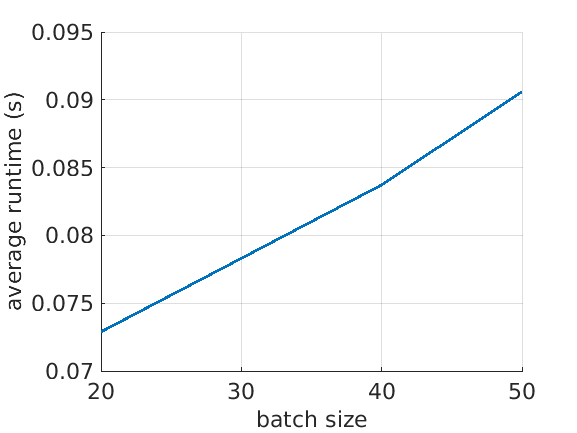

%%% batch size v.s runtime
figure;
hold on;
grid;
plot([20 40 50],[runtime1 runtime2 runtime3],'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('batch size','Fontsize',fsz);
ylabel('average runtime (s)','Fontsize',fsz);
saveas(gcf, 'slbfgs_total_runtime.png');

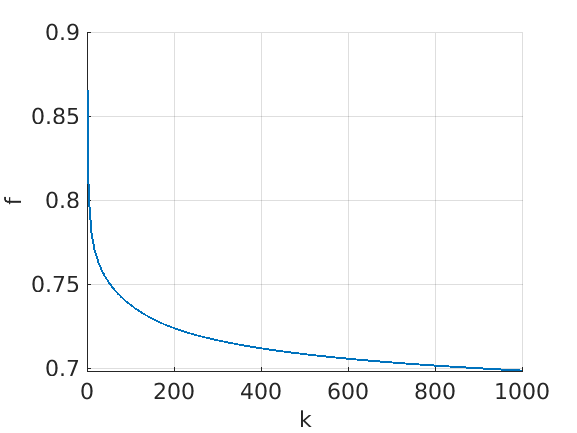

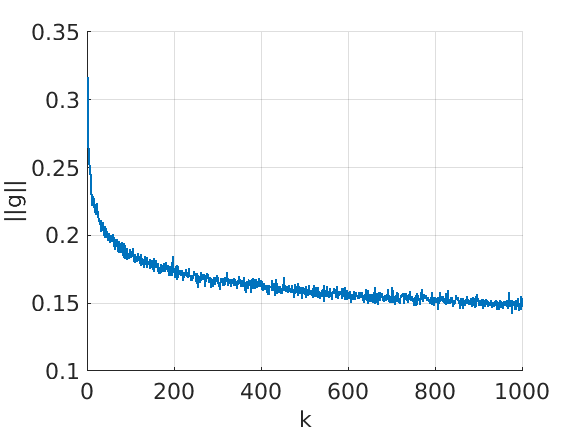

%%% 4. ng=30, nh=50;
ng = 30; nh = 50;
[fs, gs, runtime2] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_30_50')

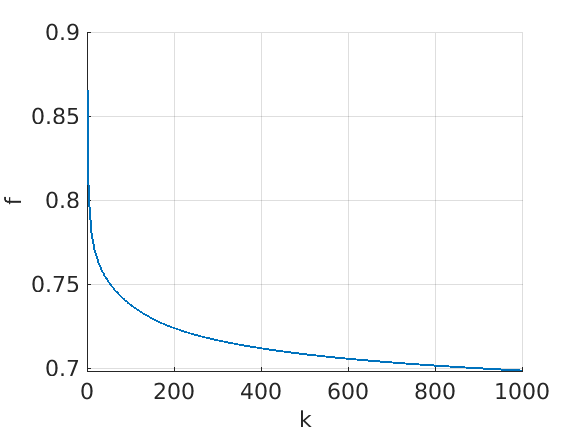

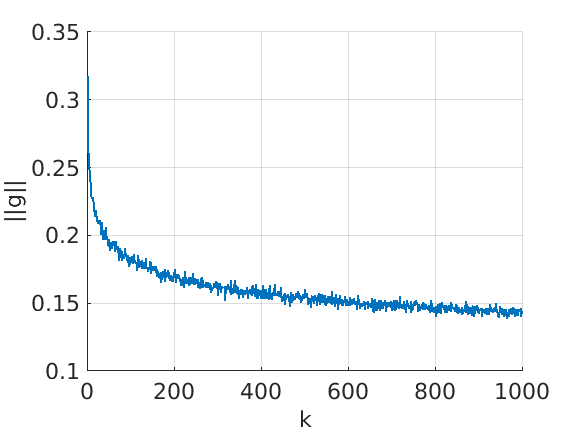

%%% 5. ng=40, nh=50;
ng = 40; nh = 50;
[fs, gs, runtime3] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_40_50')

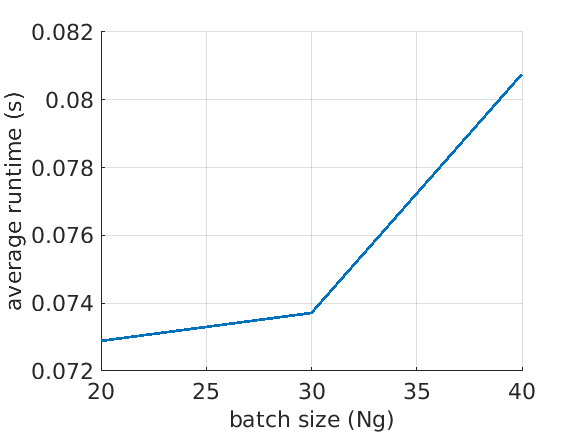

%%% batch size v.s runtime
figure;
hold on;
grid;
plot([20 30 40],[runtime1 runtime2 runtime3],'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('batch size (Ng)','Fontsize',fsz);
ylabel('average runtime (s)','Fontsize',fsz);
saveas(gcf, 'slbfgs_Ng_runtime.png');

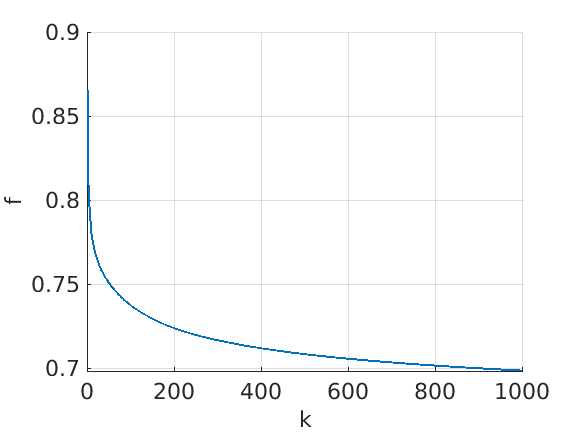

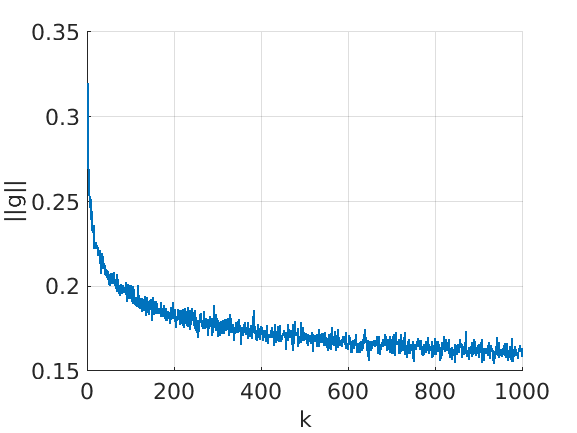

%%% 4. ng=20, nh=60;
ng = 20; nh = 60;
[fs, gs, runtime2] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_20_60')

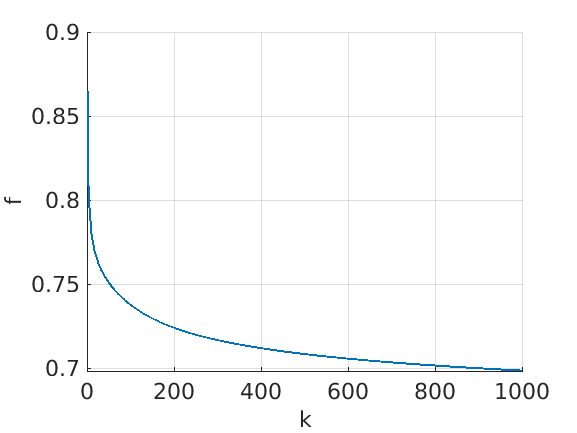

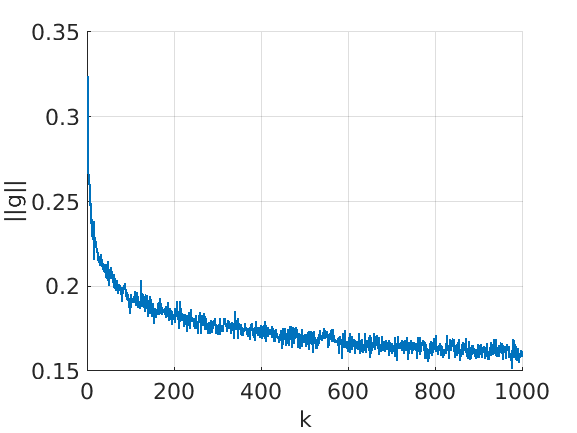

%%% 5. ng=20, nh=70;
ng = 20; nh = 70;
[fs, gs, runtime3] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_batch_20_70')

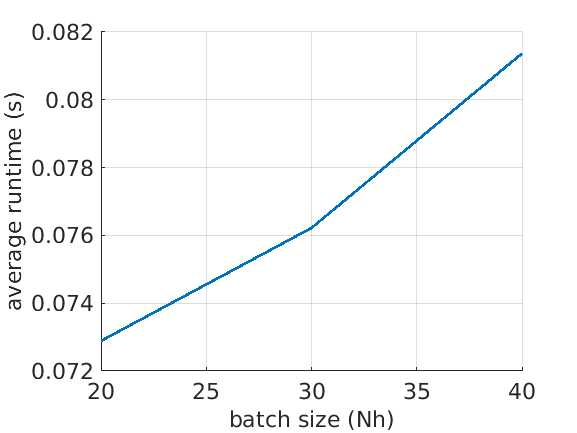

%%% batch size v.s runtime
figure;
hold on;
grid;
plot([20 30 40],[runtime1 runtime2 runtime3],'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('batch size (Nh)','Fontsize',fsz);
ylabel('average runtime (s)','Fontsize',fsz);
saveas(gcf, 'slbfgs_Nh_runtime.png');

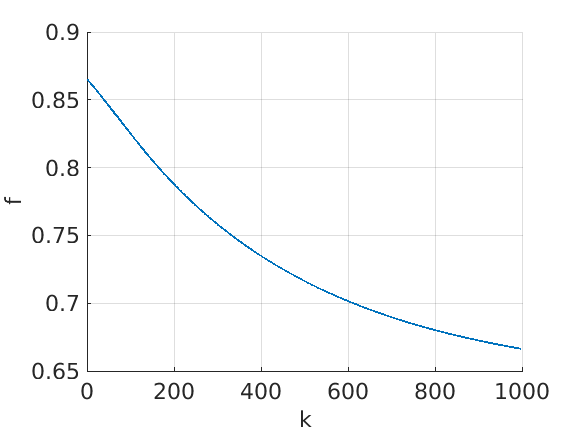

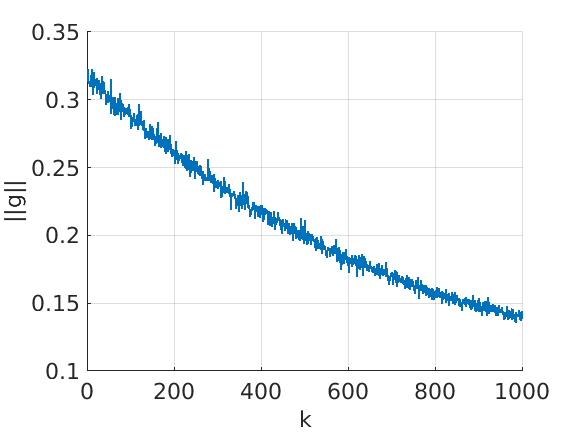

%% alpha decrease strategies:
ng = 20; nh = 50; M = 10;
%%% 1. constant;
alpha_strat = 'constant';
[fs, gs, runtime1] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_alpha_constant')

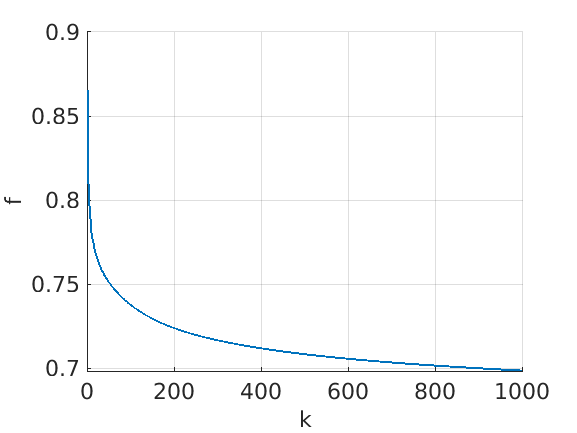

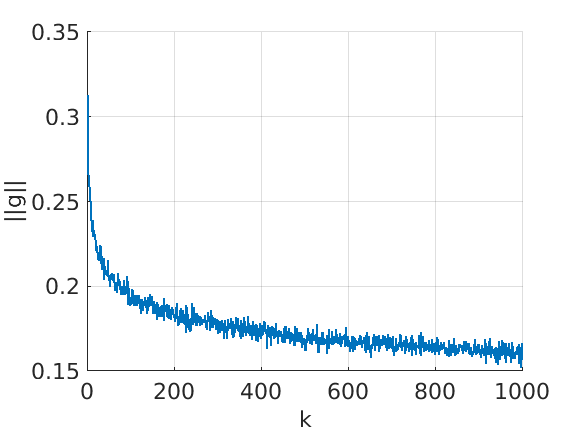

%%% 2. slow decay;
alpha_strat = 'slow';
[fs, gs, runtime2] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_alpha_slow')

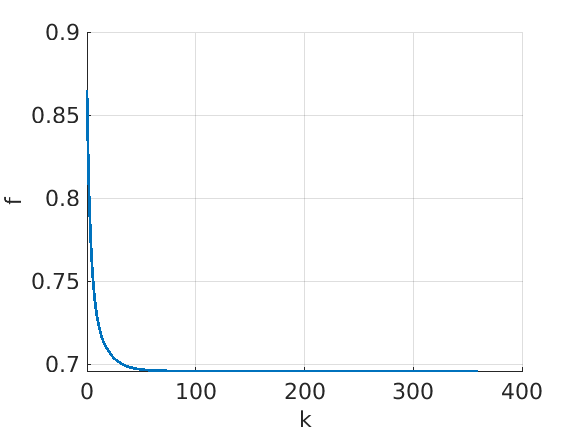

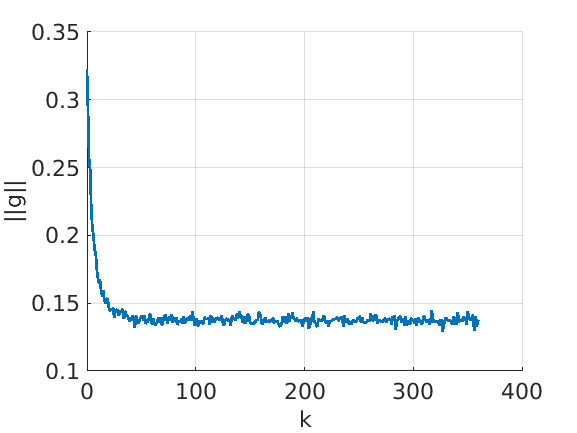

ans =     0.0734    0.0891    0.0793


%%% 3. exponential;
alpha_strat = 'exponential';
[fs, gs, runtime3] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_alpha_exponential')

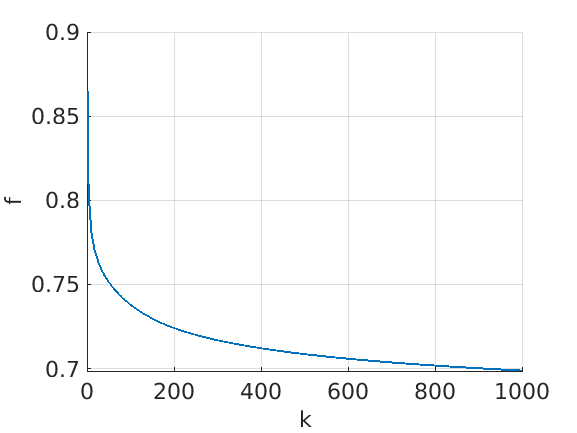

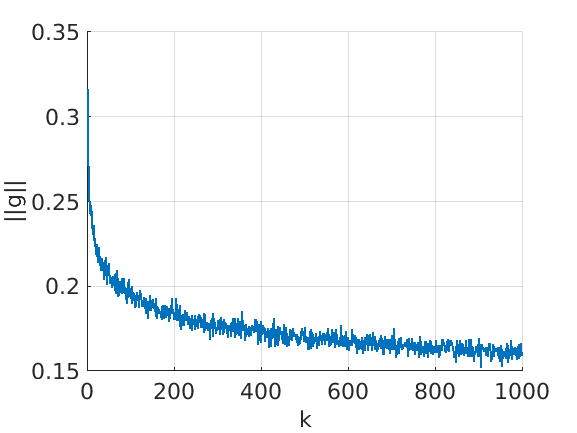

%% M:
ng = 20; nh = 50; alpha_strat = 'slow';
%%% 1. constant;
M = 10;
[fs, gs, runtime1] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_m_10')

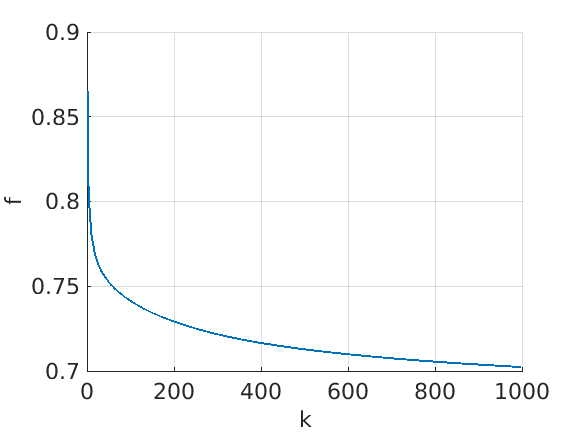

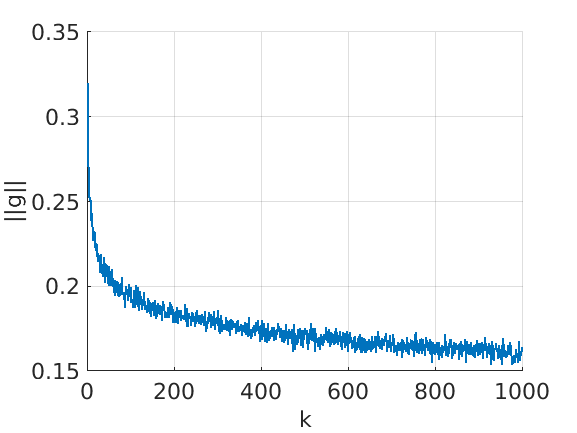

%%% 2. slow decay;
M = 20;
[fs, gs, runtime2] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_m_20')

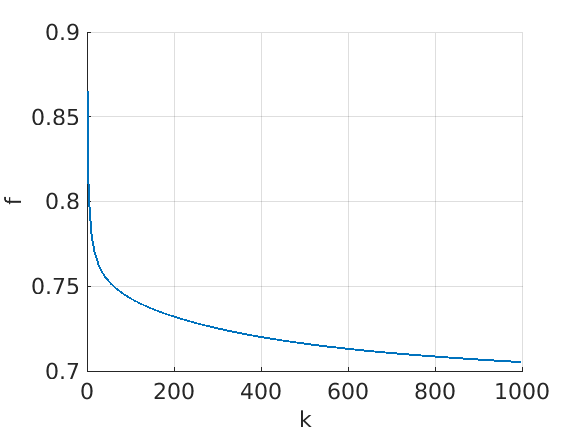

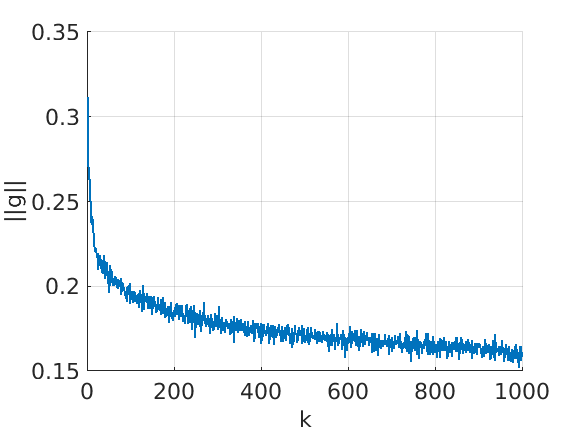

%%% 3. exponential;
M = 30;
[fs, gs, runtime3] = SLBFGS_experiment(x0,Y,fun,gfun,alpha_strat,ng,nh,M,nsteps,nruns);
SGplotting(fs,gs,'slbfgs_m_30')

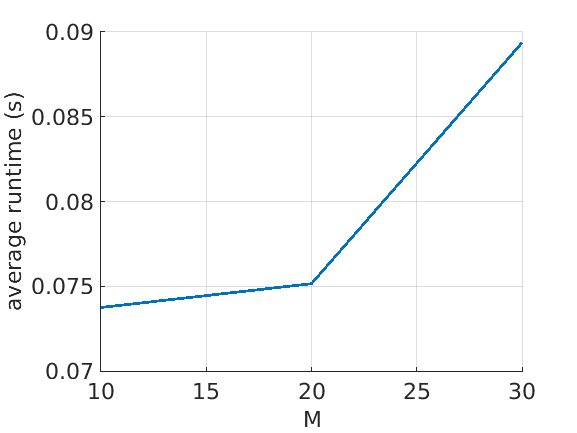

%%% batch size v.s runtime
figure;
hold on;
grid;
plot([10 20 30],[runtime1 runtime2 runtime3],'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('M','Fontsize',fsz);
ylabel('average runtime (s)','Fontsize',fsz);
saveas(gcf, 'slbfgs_M_runtime.png');

function f = fun0(I,Y,w,lam) 
f = sum(log(1 + exp(-Y(I,:)* w)))/length(I) + 0.5*lam* (w'* w);
end

function g = gfun0(I,Y,w,lam) 
aux = exp(-Y(I,:)*w);
d1 = size(Y,2);
g = sum(-Y(I,:).*((aux./(1 + aux))*ones(1,d1)),1)'/length(I) + lam*w;
end

function Hv = Hvec0(I,Y,w,v,lam)
aux = exp(-Y(I,:)*w);
d1 = size(Y,2);
Hv = sum(Y(I,:).*((aux.*(Y(I,:)*v)./((1+aux).^2)).*ones(1,d1)),1)' + lam*v;
end